# Comparing FFT, Short-Time FFT and CWT

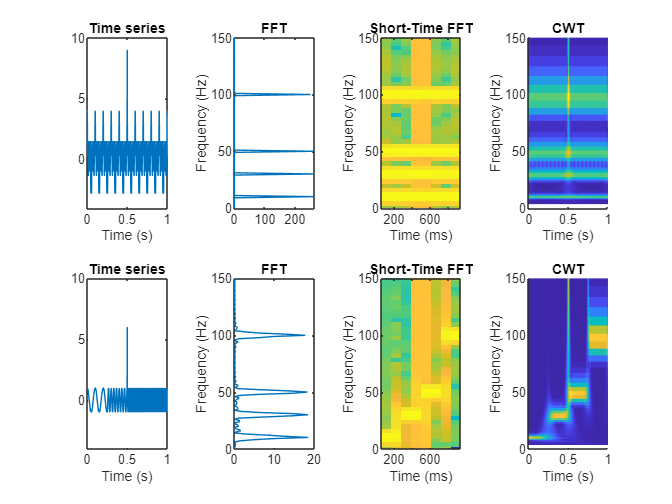

f = [10 30 50 100]; 
Fs = 1000;
t = (0:1/Fs:1)';

mask = [t<0.25  (t>=0.25&t<0.5) (t>=0.5&t<0.75) (t>0.75)];  % logical matrix

N = numel(t); 
N2 = floor(N/2);
fvec = (0:N2-1)*Fs/N;

clear signals
harmonics = cos(2*pi*t*f); 
signals = sum(harmonics,2);                           % signal 1
signals(:,2) = sum(harmonics .* mask,2);              % signal 2
signals = signals + 5*(t>=0.5&t<=0.501);              % add a peak at t = 0.5

F = abs(fft(signals)).^2/N;                           % compute FFT

figure(Color='w')
tiledlayout(2,4)
fMax = 150;
for i = 1:size(signals,2)                                     
     nexttile
     plot(t, signals(:,i))                            % plot signal in time domain
     xlabel("Time (s)")
     title("Time series")
     ylim([-4 10])
     
     ax(1)=nexttile;
     plot(F(1:N2,i), fvec)                            % plot FFT
     ylabel("Frequency (Hz)"), title("FFT")
     
     ax(2)=nexttile;
     spectrogram(signals(:,i),[],[],[],Fs, 'yaxis')   % compute and visualize short-time FFT
     colorbar("off")
     title("Short-Time FFT")
     
     [cfs,frq] = cwt(signals(:,i), "morse", Fs);      % compute CWT 
  
     ax(3)=nexttile;
     surface(t,frq,abs(cfs))                          % visualize scalogram
     axis tight, shading flat
     xlabel("Time (s)"), ylabel("Frequency (Hz)")
     title("CWT")
     set(ax,'YLim',[0, fMax])
end